# Stima LS di segnali sinusoidali

Sono stati acquisiti, con frequenza di campionamento $f_S = 1 \;\text{kHz}$, $1000$ campioni di un segnale $y(t)$ costituito dalla somma di due segnali sinusoidali 


$$y(t) = \vartheta_1\cdot \sin\left(\bar{\omega}_1\,t+\bar{\delta}_1\right) + \vartheta_2\cdot \cos\left(\bar{\omega}_2\,t+\bar{\delta}_2\right)+\epsilon(t)  \qquad t=k \Delta\,,\quad k=1,\,2,\,\ldots\,N $$


Del segnale sono **noti** i seguenti parametri:

- pulsazione $\bar{\omega}_1$ : $\bar{\omega}_1 = 2\,\pi\cdot 50 \; \text{rad/s}$

- pulsazione $\bar{\omega}_2$ : $\bar{\omega}_2 = 2\,\pi\cdot 150  \; \text{rad/s}$

- sfasamento $\bar{\delta}_1$ : $\bar{\delta}_1 = -\frac{\pi}{9}$

- sfasamento $\bar{\delta}_2$ :  $\bar{\delta}_2 = \frac{2\,\pi}{5}$

mentre sono **incogniti** i valori delle ampiezze $\vartheta_1$ e $\vartheta_2$.

I campioni acquisiti ed i valori dei parametri noti sono a disposizione nel MAT file "StimaLS.MAT"

Determinare i valori dei parametri incogniti $\vartheta_1$ e $\vartheta_2$ utilizzando uno **stimatore ai minimi quadrati.**

**Suggerimento**

L' espressione di $y(t)$ può essere riscritta in questo modo


$$y(t) = \varphi^{\top}(t) \cdot \vartheta + \epsilon(t)$$


dove


$$\varphi(t) = \left[ \begin{array}{c} \varphi_1(t) \\ \varphi_2(t) \end{array} \right] \qquad \vartheta =  \left[ \begin{array}{c} \vartheta_1 \\ \vartheta_1 \end{array} \right]$$


clear
close all
clc

load StimaLS.MAT

Fs = 1e3; % kHz
Ts = 1/Fs;

omega1 = 2*pi*50;
omega2 = 2*pi*150;
delta1 = -pi/9;
delta2 = 2*pi/5;

figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.75]);
plot(t, y_t, 'LineWidth', 1.5);

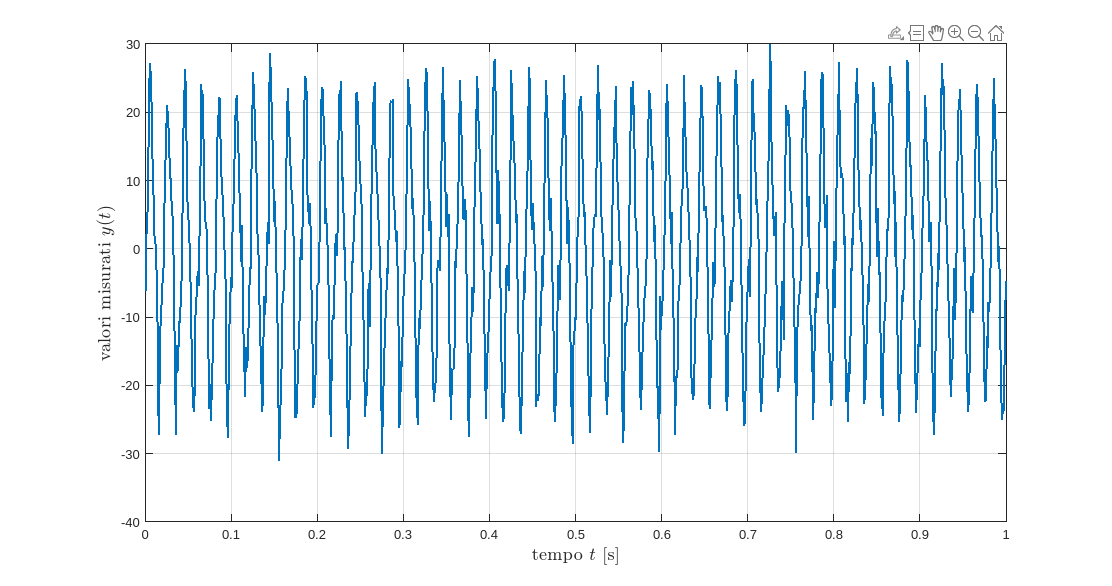

grid on;
xlabel('tempo $t$ [s]','Interpreter','latex','FontSize',14);
ylabel('valori misurati $y(t)$','Interpreter','latex','FontSize',14);

% inserisci qua il tuo codice

y_t = y_t';
phi = [  cos(omega2 * t + delta2);
    sin(omega1 * t + delta1)]';


$$\Phi * \theta = y$$


theta = phi \ y_t % expected 5 and 20

theta =     4.9550
   19.8294


y_pred = theta(1) * phi(:,1) + theta(2) * phi(:,2);

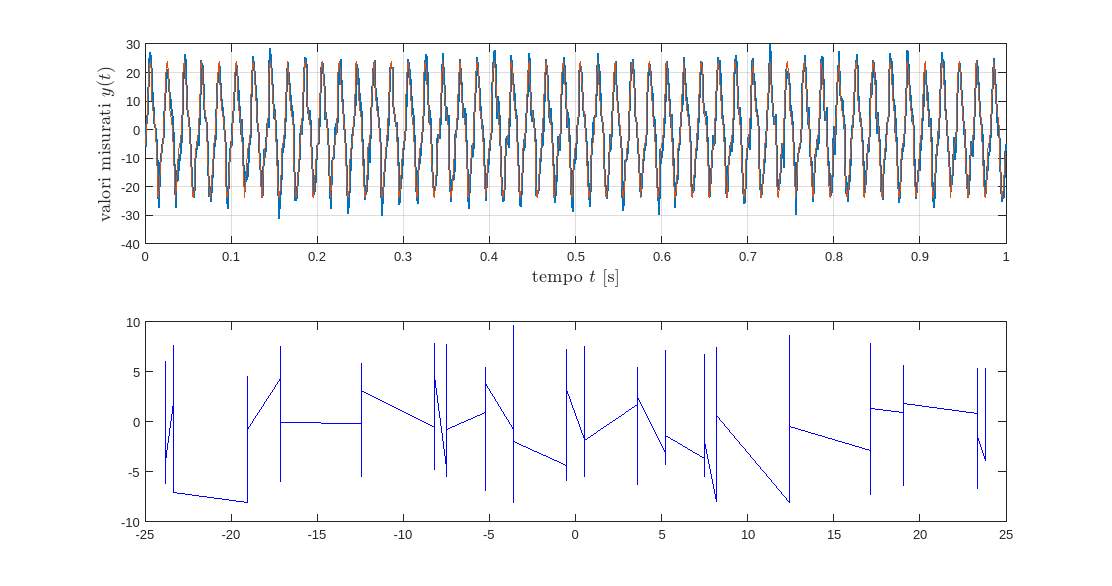

figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.75]);
subplot(2,1,1)
plot(t, y_t, 'LineWidth', 1.5);
grid on;
hold on;
plot(t, y_pred);
xlabel('tempo $t$ [s]','Interpreter','latex','FontSize',14);
ylabel('valori misurati $y(t)$','Interpreter','latex','FontSize',14);

subplot(2,1,2);

grid on; 
errors = y_pred - y_t;

[ys, idx]= sort(y_pred);
plot(ys, errors(idx), '-b');

errors = y_t - y_pred;
mean(errors)

ans = 0.0210


var(errors) % expected is 10

ans = 9.0767